# 共通設定

dt = 0.01;  % サンプリング時間

# 安全制御（衝突回避）

t_end = 7; % シミュレーション時間

p_init = [3, -2];    % 初期位置
p_r = [-3, 2.5];  % 目標位置

kp = 1; % フィードバックゲイン

ganmm = 10;
p_obs = [0, 0];
delta_obs = 0.5;

## シミュレーションの実行

slx_model_name = 'safe_control';    % simulinkファイルの名前
out = sim(slx_model_name);

## 結果の表示

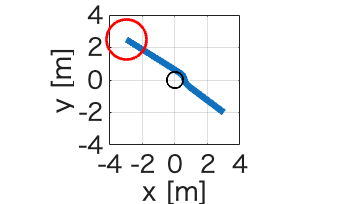

% figure
% plot(out.tout, out.position, "LineWidth", 5)
% yline(p_r, "LineWidth", 3)
% fontsize(18, "points")
% xlabel('Time [s]')
% ylabel('x, y [m]')
% legend('x', 'y')
% grid on
% 
% figure
% plot(out.tout, out.h, "LineWidth", 5)
% yline(0, "LineWidth", 3)
% fontsize(18, "points")
% xlabel('Time [s]')
% ylabel('safety margin')
% grid on
% 
z = 0:0.05:2*pi;
x_obs = delta_obs*cos(z);
y_obs = delta_obs*sin(z);
% figure
% plot(p_r(1), p_r(2), "ko", "LineWidth", 2, "MarkerSize", 30, "Color", 'r');
% hold on
% plot(x_obs, y_obs, "k", "LineWidth", 1.5);
% h = plot(p_init(1), p_init(2), "b.", "MarkerSize", 60);
% hold off
% fontsize(18, "points")
% axis equal
% grid on
% xlim([-4, 4]); ylim([-4, 4])
% for i=1:1:length(out.tout)
%     h.XData = out.position(i,1);
%     h.YData = out.position(i,2);
%     pause(0.03);
%     drawnow limitrate; 
% end


figure
plot(out.position(:,1), out.position(:,2), "LineWidth", 5);
hold on
plot(p_r(1), p_r(2), "ko", "LineWidth", 2, "MarkerSize", 30, "Color", 'r');
plot(x_obs, y_obs, "k", "LineWidth", 1.5);
hold off
fontsize(18, "points")
axis equal
grid on
xlim([-4, 4]); ylim([-4, 4])
xlabel('x [m]')
ylabel('y [m]')

 
save data10 out p_r x_obs y_obs